# **Worksheet 1: Intro to MATLAB Live Scripts**

**Directions: ****Change your working directory to your Flash drive and save this file on it.** Read through this document and run any Example code. Then try the Problems yourself. The solutions will be posted on Canvas later. When you've completed the Worksheet, you can start the Lab.

This is a MATLAB live script, which lets you (1) write text in a word processed way similar to Microsoft Word or a Google Doc, and (2) also include MATLAB code that you can run. The white boxes (like this) are the text environments. The gray boxes below are code environments, and you can see the line numbers for them on the left. You can make a code environment when you're in a text environment by clicking "Code" on the Live Editor ribbon and vice versa, you can make a text environment when you're in a code environment by clicking "Text" on the Live Editor ribbon. You can break up the live script into sections by using "Section Break" on the ribbon above and then just run code in that particular section.

**PROBLEM #1: **Calculate the following values using MATLAB in the code block below. You can use MATLAB's Help to assist in determining syntax. When you're done entering the code, use "Run Section" (not the full "Run"!). You should see your output in the panel to the right.

a) $log(5)$ (Note, this is common log, so base 10.)

b) $ln(5)$

c) $log_2(5)$

d) $e^2$

% Put your code here.
log10(5)

ans = 0.6990

log(5)

ans = 1.6094

log2(5)

ans = 2.3219

exp(2)

ans = 7.3891

**PROBLEM #2:  **Run the code below.

x = 5;
x = x + 3;
y = 'I love MATLAB!';

The 2nd line of code is x = x +3. The math equation $x = x + 3$ should not make sense for any value of $x$. However, this isn't a line of math, it's a line of code. Explain in words what that line did.

ANSWER: It took the variable x which was initialized as an integer value in line 7 and added 3 to it.

Now experiment with adding semicolons ; to the end of each of the lines and run the it again. What does the presence or lack thereof of a semicolon do in MATLAB? Does every executable statement in MATLAB need a semicolon? When should we include them and when shouldn't we?

ANSWER: It didn't display the values. Any executable statement that we want to be displayed to the cmd needs to not have a ;.

Look in the Workspace window of MATLAB. You should see the variable name x show up. You can see the variable's value, its size (because it's an array, so that's referring to the dimensions), and its Class. What is x's class and *generally* what does that mean? What about y?

ANSWER: X is a 1x1 double (array class), meaning that it is a 1x1 matrix. 

**PROBLEM #3:** Run the code. Your input prompts will appear in the Command Window.

x = input('Enter a value for x ');
y = input('Enter a value for y ');
z = x + y;
fprintf('The sum of the numbers is %4.1f\n', z);

The sum of the numbers is  6.7


When you're prompted, set x as 1.234 and y as 5.5. What is the answer? What happened to x and y's class(es), as seen in the Workspace? Look at the output to the right and compare it to z's value in the Workspace, what's going on?

ANSWER: The printed answer is 6.7, whereas z = 6.7340. The %4.1f\n rounds our answer to 1 decimal place.

**PROBLEM #4: **Experiment with the fprintf statement. Re-run the code in this part of the live script by creating a Code block yourself below this paragraph by Clicking "Code" on the ribbon above while your cursor is at the end of this paragraph. You should rerun the code with the %4.1f changed to %5.5f. Repeat with %4.2e, %4.3E, %d, %g**. **Run the MATLAB command "doc fprintf" and click on the blue "formatSpec" to find out what the different formatting specifications mean.

x = input('Enter a value for x ');
y = input('Enter a value for y ');
z = x + y;
fprintf('The sum of the numbers is %g\n', z);

The sum of the numbers is 6.734


**PROBLEM #5: **Write MATLAB code in the code block below to convert a temperature from Celsius to Fahrenheit: the conversion formula is $F = \frac{9}{5}C + 32$. Don't worry about detailed commenting, there should just be an input, a formula, and an output. Consider the formatting of your output, though, especially the kind of number that should be displayed.

% Put your code here.

c = 100

c = 100

f = (9/5)*c + 32;
fprintf('The number in Celsius converted to Fahrenheight is %g\n', f)

The number in Celsius converted to Fahrenheight is 212


EXAMPLE #1: Notice that you can create nicely formatted math symbols in these text boxes by making a LaTeX code environment (it's okay if you don't know what that means). Basically, by enclosing some LaTeX code between $'s, you're able to make it look fancy. For example, if I type:

$x^2 - y_1^3 + \alpha + \cos{\omega} - \sqrt{x}$

and hit enter, I get...


$$x^2 - y_1^3 + \alpha + \cos{\omega} - \sqrt{x}$$


You can click on the fancy math symbols above and it'll open up an equation editor where you can see how it formatted it. Or, single click on it and hit Backspace (Delete on a Mac) and you'll see the LaTeX code inline.

**PROBLEM #6: **Write out the Pythagorean Theorem in two ways typeset using LaTeX code below. Note that the Pythagorean Theorem only applies to *right* triangles.

a) write the equation that says the sum of the squares of the two legs, $a$ and $b$, is equal to the square of the hypotenuse, $c$. 


$$a^2 +b^2 =c^2$$


b) write the equation solved for $c$. 


$$c=\sqrt{a^2 +b^2 }$$


EXAMPLE #2: MATLAB is also really great at plotting! For example, we can plot the graph of $y = \sin{x}$ using MATLAB like so:

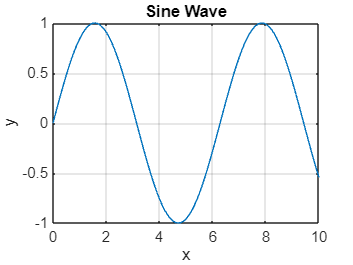

% Sample data for plotting
x = 0:0.1:10; % x will start at 0 and end at 10 with points every 0.1 increment.
y = sin(x);

% Create a figure and plot the data
figure;
plot(x, y);
title('Sine Wave');
xlabel('x');
ylabel('y');

% Add grid lines for better visualization
grid on;

% Add custom axes limits
xlim([0 10]);
ylim([-1 1]);

EXAMPLE #3: Now let's plot a small scatter plot of the points $(1,3), (2,4), (3,2), (4,2),(5,3)$.

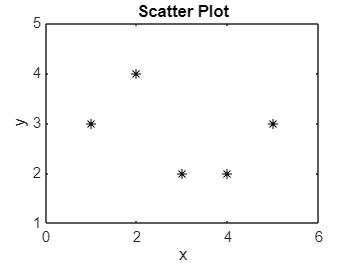

% Sample data for plotting
x = [1 2 3 4 5];
y = [3 4 2 2 3];

% Create a figure and plot the data
figure;
plot(x, y,'k*');
title('Scatter Plot');
xlabel('x');
ylabel('y');

% Add custom axes limits
xlim([min(x)-1 max(x)+1]);
ylim([min(y)-1 max(y)+1]);

Notice the 'k*' option listed in the plot command. The k is saying to make the curve blac**k** and the * is saying to use *'s as the line style.

You should check out MATLAB's documentation on the plot command for lots of details on plotting style.

**PROBLEM #7: **Plot $y=cos(x)$ over the interval $[-2\pi,2\pi]$ using a **red** curve made up of dots every 0.25 units. Pick an appropriate title, axes labels, and axes limits and include a grid.

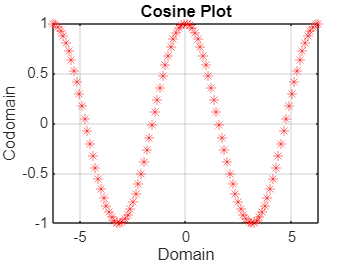

% Put your plotting code here.
x = linspace(-2*pi, 2*pi,100);
y = cos(x);

figure
plot(x,y,'r*',LineWidth=0.25)
title('Cosine Plot')
xlabel('Domain')
ylabel('Codomain')
grid on